# Pulse detector test bench (step 4)

© 2019 The MathWorks, Inc.

This test bench creates a reference pulse detection algorithm, simulates the Simulink model implementation, and compares the Simulink result to the MATLAB reference.

## Create reference algorithm & parameters

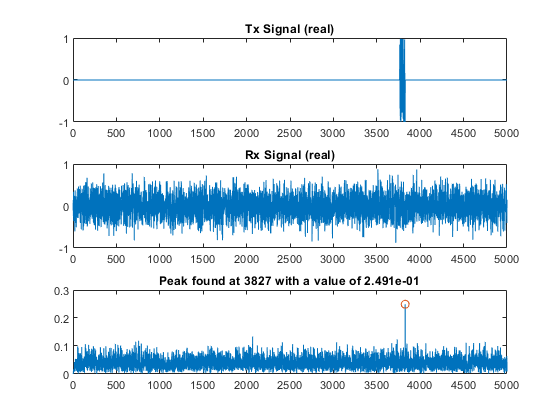

pulse_detector_reference;

## Simulate model and compare results to reference

% Simulate in fixed-point or floating-point
if 1 % fixed-point
    DT_input = fixdt(1,16,14);
    DT_coeff = fixdt(1,18);
    DT_filter = fixdt(1,18,15);
    DT_power = fixdt(1,18,11);
else
    DT_input = 'double';
    DT_coeff = 'double';
    DT_filter = 'double';
    DT_power = 'double';
end

if iscolumn(CorrFilter)
    CorrFilter = transpose(CorrFilter); % need row vector for filter block
end
SimTime = length(RxSignal) + WindowLen + 30;

% Simulate model
sim('pulse_detector_v4')

% Correlation filter output
FilterOutSL = squeeze(logsout.getElement('filter_out').Values.Data);
FilterValid = squeeze(logsout.getElement('filter_valid').Values.Data);
FilterOutSL = FilterOutSL(FilterValid);
compareData(real(FilterOut),real(FilterOutSL),{2 3 1},'ML vs SL correlator output (re)');


Maximum error for ML vs SL correlator output (re) out of 5000 values
 8.185188e-06 (absolute), 3.299330e-03 (percentage)


compareData(imag(FilterOut),imag(FilterOutSL),{2 3 2},'ML vs SL correlator output (im)');


Maximum error for ML vs SL correlator output (im) out of 5000 values
 7.820518e-06 (absolute), 6.416683e-03 (percentage)


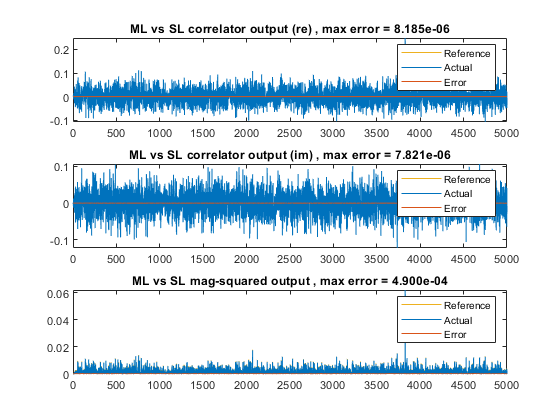


Maximum error for ML vs SL mag-squared output out of 5000 values
 4.900454e-04 (absolute), 7.897154e-01 (percentage)



% Magnitude squared output
MagSqSL = squeeze(logsout.getElement('mag_sq_out').Values.Data);
MagSqSL = MagSqSL(FilterValid);
compareData(MagSqOut,MagSqSL,{2 3 3},'ML vs SL mag-squared output');


% Peak value
MidSampleSL = squeeze(logsout.getElement('mid_sample').Values.Data);
Detected = squeeze(logsout.getElement('detected').Values.Data);
PeakSL = double(MidSampleSL(Detected>0));

fprintf('\nPeak location = %d, magnitude = %.3d using global max\n',location,peak);


Peak location = 3827, magnitude = 2.491e-01 using global max


fprintf('Peak location = %d, mag-squared = %.3d using local max\n',location_2,peak_2);

Peak location = 3827, mag-squared = 6.205e-02 using local max


fprintf('Peak mag-squared from Simulink = %.3d, error = %.3d\n',PeakSL,abs(peak_2-PeakSL));

Peak mag-squared from Simulink = 6.201e-02, error = 4.170e-05
